# Visumotor map determines how visually guided reachign movements are corrected within and across trials - Hayashi et al

clear; clc; cd('/Users/duncan/Dropbox/BIOMS/Qualifying/Exam/Hayashi/Code')


## Experiment 1 protocol

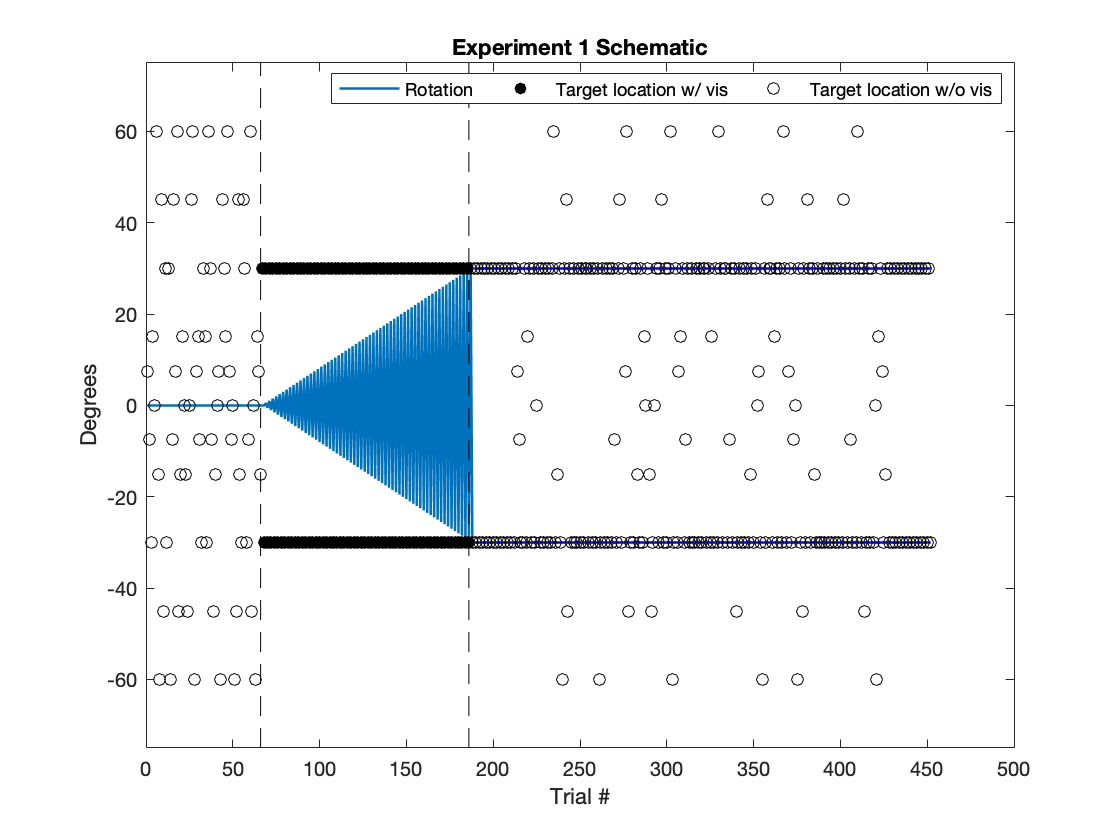

% Perturbation 
rotation = zeros(188,1);
% Gradual increase/decrease
pos_grad = 0:0.5:30;
neg_grad = 0:-0.5:-30;
% Index into schedule
a = 1;
for i = 67:188
    if rem(i,2) ~= 0
        rotation(i) = pos_grad(a);
    else
        rotation(i) = neg_grad(a); 
        a = a+1;
    end
end
pos_rot = nan(452,1);
neg_rot = nan(452,1);
pos_rot(189:452) = 30;
neg_rot(189:452) = -30;

% Targets 
exp1_targ = nan(452,1);
% Probe trial target locations
probe = [0;7.5;-7.5;15;-15;30;-30;45;-45;60;-60];

% Randomly pick location for baseline 
baseline_probe_trials = nan(11,6);
for i = 1:6
    baseline_probe_trials(:,i) = datasample(probe,11, 'replace', false);
end
baseline_probe_trials = baseline_probe_trials(:);
% Index in 
exp1_targ(1:66) = baseline_probe_trials;
b = 1;
for i = 67:188
    if b == 1
        exp1_targ(i) = 30;
        b = 0;
    else 
        exp1_targ(i) = -30;
        b = 1;
    end
end

% Post intervention: probe trials interleaved into regular reaches 
post_probe_trials = datasample(211:427,66, 'replace', false);
a = 1;
b = 1;
for i = 187:452
    if sum(post_probe_trials == i) == 1
        exp1_targ(i) = baseline_probe_trials(a);
        a = a+1;
    else 
        if b == 1
            exp1_targ(i) = 30;
            b = 0;
        else
            exp1_targ(i) = -30;
            b = 1;
        end
    end
end

% Plot 
figure;
p = plot(rotation, 'linewidth', 1.25);
hold on 
plot(pos_rot, 'b-', 'linewidth', 1.25)
plot(neg_rot, 'b-', 'linewidth', 1.25)
xlabel('Trial #')
ylabel('Degrees')
wo = plot(exp1_targ, 'ko');
w = scatter(67:186, exp1_targ(67:186), 'k', 'filled');
title('Experiment 1 Schematic')
ylim([-75 75])
g = gca;
line([66 66], [g.YLim(1) g.YLim(2)], 'color', 'k', 'linestyle', '--')
line([186 186], [g.YLim(1) g.YLim(2)], 'color', 'k', 'linestyle', '--')
legend([p, w, wo], {'Rotation', 'Target location w/ vis', 'Target location w/o vis'}, 'numcolumns', 3, 'location', 'best')

% saveas(gcf, 'exp1_schematic.jpg')
% unclear if reaches to +-30 after intervention were w/ or w/o vision 


## Experiment 2 protocol

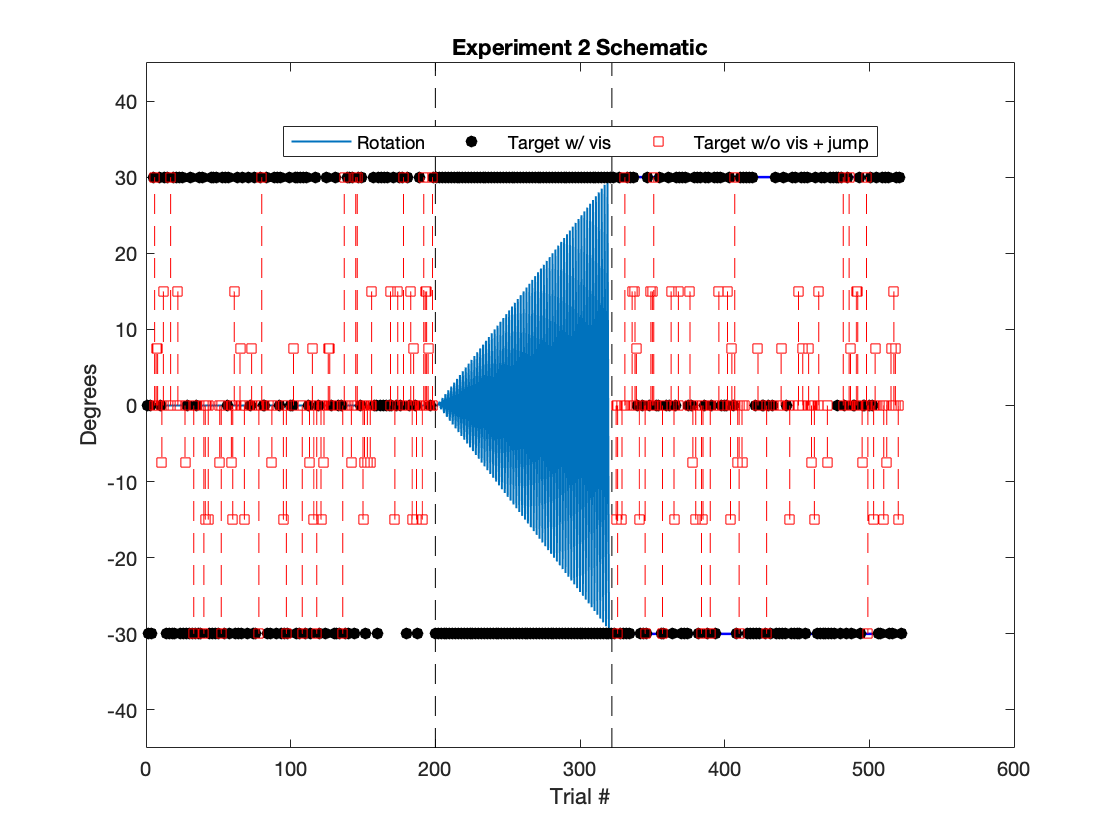

clear; clc

% Rotation 
rotation = zeros(320,1);
% Gradual increase/decrease
pos_grad = 0:0.5:30;
neg_grad = 0:-0.5:-30;
% Index into schedule
a = 1;
for i = 201:320
    if rem(i,2) ~= 0
        rotation(i) = pos_grad(a);
    else
        rotation(i) = neg_grad(a); 
        a = a+1;
    end
end
pos_rot = nan(522,1);
neg_rot = nan(522,1);
pos_rot(321:522) = 30;
neg_rot(321:522) = -30;

% Targets 
exp2_targ = nan(522,1);

% alternating targets during adaptation
b = 1;
for i = 201:322
    if b == 1
        exp2_targ(i) = 30;
        b = 0;
    else 
        exp2_targ(i) = -30;
        b = 1;
    end
end

% First 200 
% split between 100 to +/-30 and 100 to 0
z = datasample(1:200, 100, 'replace', false);
for i = 1:200
    if sum(z == i) == 1
        exp2_targ(i) = 0;
    else 
        if rem(i,2) ~= 0
            exp2_targ(i) = 30;
        else 
            exp2_targ(i) = -30;
        end
    end
end

% reaches to 0, connect to a random jump target 
probe = [0;7.5;-7.5;15;-15;30;-30];
rndjump = datasample(probe, 70);
jumpto1 = nan(200,1);
a = 1;
for i = 1:200
    if sum(z(31:100) == i) == 1
        jumpto1(i) = rndjump(a);
        a = a+1;
    end
end

% Second 200 
% split between 100 to +/-30 and 100 to 0
zz = datasample(323:522, 100, 'replace', false);
for i = 323:522
    if sum(zz == i) == 1
        exp2_targ(i) = 0;
    else 
        if rem(i,2) ~= 0
            exp2_targ(i) = 30;
        else 
            exp2_targ(i) = -30;
        end
    end
end

% reaches to 0, connect to a random jump target 
rndjump = datasample(probe, 70);
jumpto2 = nan(519,1);
a = 1;
for i = 323:522
    if sum(zz(31:100) == i) == 1
        jumpto2(i) = rndjump(a);
        a = a+1;
    end
end


% Plot 
figure;
% rotation schedule
p = plot(rotation, 'linewidth', 1); 
hold on 
plot(pos_rot, 'b-', 'linewidth', 1.25)
plot(neg_rot, 'b-', 'linewidth', 1.25)
xlabel('Trial #')
ylabel('Degrees')
title('Experiment 2 Schematic')
ylim([-45 45])
g = gca;
% separate blocks
line([200 200], [g.YLim(1) g.YLim(2)], 'color', 'k', 'linestyle', '--')
line([322 322], [g.YLim(1) g.YLim(2)], 'color', 'k', 'linestyle', '--')
% No rotation +/- 30 reaches 
for i = 1:length(exp2_targ)
    if exp2_targ(i) ~= 0
        t = scatter(i,exp2_targ(i), 'k', 'filled');
    end
end
% Block1 Normal/jump reaches 
for i = 1:length(z)
    if i <= 30
        scatter(z(i), exp2_targ(z(i)), 'k', 'filled');
    else
        tnv = plot(z(i), exp2_targ(z(i)), 'rs');
    end
end
% Connect jump reaches to jump target location
for i = 1:length(jumpto1)
    if ~isnan(jumpto1(i))
        plot(i, jumpto1(i), 'rs')
        line([i i], [0 jumpto1(i)], 'color', 'r', 'linestyle', '--')
    end
end
% Block2 Normal/jump reaches 
for i = 1:length(zz)
    if i <= 30
        scatter(zz(i), exp2_targ(zz(i)), 'k', 'filled');
    else
        tnv = plot(zz(i), exp2_targ(zz(i)), 'rs');
    end
end
% Connect jump reaches to jump target location
for i = 1:length(jumpto2)
    if ~isnan(jumpto2(i))
        plot(i, jumpto2(i), 'rs')
        line([i i], [0 jumpto2(i)], 'color', 'r', 'linestyle', '--')
    end
end

legend([p, t, tnv], {'Rotation', 'Target w/ vis', 'Target w/o vis + jump'}, 'numcolumns', 3, 'location', 'best')
% saveas(gcf, 'exp2_schematic.jpg')

## Experiment 3 protocol

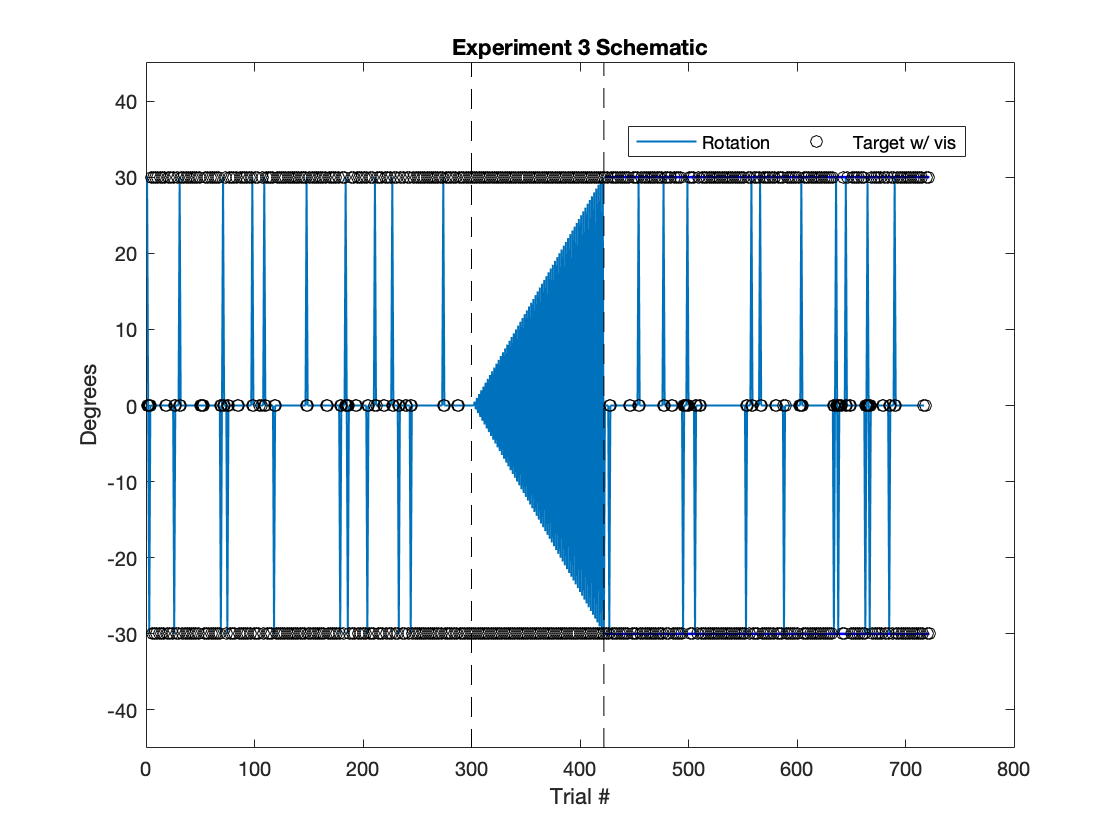

clear; clc;

% Rotation 
rotation = zeros(422,1);
% Gradual increase/decrease
pos_grad = 0:0.5:30;
neg_grad = 0:-0.5:-30;
% Index into schedule
a = 1;
for i = 301:422
    if rem(i,2) ~= 0
        rotation(i) = pos_grad(a);
    else
        rotation(i) = neg_grad(a); 
        a = a+1;
    end
end
pos_rot = nan(722,1);
neg_rot = nan(722,1);
pos_rot(423:722) = 30;
neg_rot(423:722) = -30;

% Targets 
exp3_targ = nan(722,1);

% alternating targets during adaptation
b = 1;
for i = 301:422
    if b == 1
        exp3_targ(i) = 30;
        b = 0;
    else 
        exp3_targ(i) = -30;
        b = 1;
    end
end

% Before adaptation 
% randomly select "pairs" of rotation trials + select rotation magnitude
z = datasample(1:300, 30, 'replace', false);
for i = 1:10
    zrot(:,i) = datasample([0,-30,30], 3, 'replace', false);
end
zrot = zrot(:);
% Make sure probe trials aren't on top of each other 
z = sort(z, 'ascend'); 
for i = 1:length(z)-1
    while z(i+1) - z(i) < 2
        z(i+1) = z(i+1)+1;
    end
end
% Sort target & rotation 
a = 1;
b = 1;
for i = 1:300
    if sum(z == i) == 1
        exp3_targ(i:i+1) = 0;
        rotation(i) = zrot(a);
        a = a+1;
    else 
        if isnan(exp3_targ(i)) && b == 1
            exp3_targ(i) = 30;
            b = 0;
        elseif isnan(exp3_targ(i)) && b == 0
            exp3_targ(i) = -30;
            b = 1;
        end
    end
end


% After adaptation 
zz = datasample(422:722, 30, 'replace', false);
for i = 1:10
    zzrot(:,i) = datasample([0,-30,30], 3, 'replace', false);
end
zzrot = zzrot(:);
% Make sure probe trials aren't on top of each other 
zz = sort(zz, 'ascend'); 
for i = 1:length(zz)-1
    while zz(i+1) - zz(i) < 2
        zz(i+1) = zz(i+1)+1;
    end
end
% Sort target & rotation 
a = 1;
b = 1;
for i = 422:722
    if sum(zz == i) == 1
        exp3_targ(i:i+1) = 0;
        rotation(i) = zzrot(a);
        a = a+1;
    else 
        if isnan(exp3_targ(i)) && b == 1
            exp3_targ(i) = 30;
            b = 0;
        elseif isnan(exp3_targ(i)) && b == 0
            exp3_targ(i) = -30;
            b = 1;
        end
    end
end

% Plot 
figure;
% rotation schedule
p = plot(rotation, '-', 'linewidth', 1); 
hold on 
plot(pos_rot, 'b-', 'linewidth', 1.25)
plot(neg_rot, 'b-', 'linewidth', 1.25)
xlabel('Trial #')
ylabel('Degrees')
title('Experiment 3 Schematic')
ylim([-45 45])
g = gca;
% separate blocks
line([300 300], [g.YLim(1) g.YLim(2)], 'color', 'k', 'linestyle', '--')
line([422 422], [g.YLim(1) g.YLim(2)], 'color', 'k', 'linestyle', '--')
t = plot(exp3_targ, 'ko');
legend([p,t], {'Rotation', 'Target w/ vis'}, 'numcolumns', 2, 'location', 'best')
% saveas(gcf, 'exp3_schematic.jpg')

## Relationship between figure (4 & 8)C and (4 & 8)D

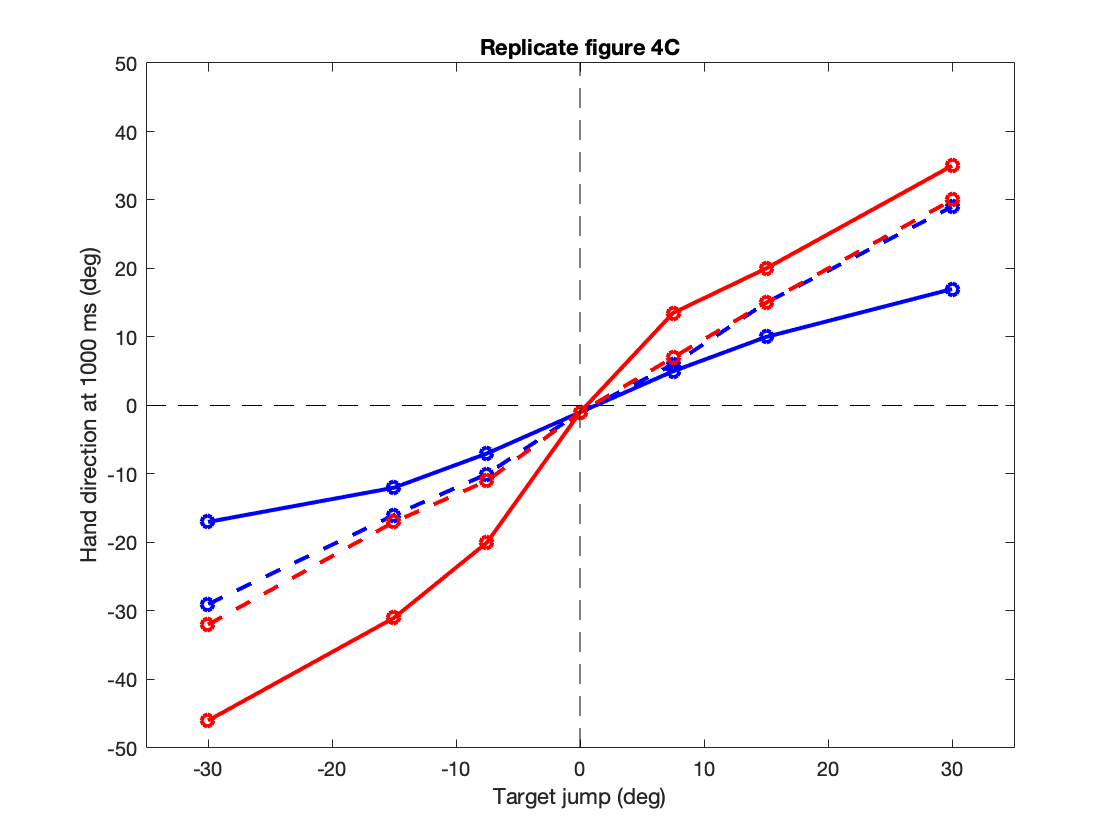

% 4 
target_jump = [-30;-15;-7.5;0;7.5;15;30];
preI_movedir = [-29;-16;-10;-1;6;15;29];
postI_movedir = [-17;-12;-7;-1;5;10;17];
preO_movedir = [-32;-17;-11;-1;7;15;30];
postO_movedir = [-46;-31;-20;-1;13.5;20;35];

% check to see if close to figure 4C
figure;
plot(target_jump, preI_movedir, 'bo--', 'linewidth', 2)
hold on 
plot(target_jump, postI_movedir, 'bo-', 'linewidth', 2)
plot(target_jump, preO_movedir, 'ro--', 'linewidth', 2)
plot(target_jump, postO_movedir, 'ro-', 'linewidth', 2)
axis([-35 35 -50 50])
plot([0 0], get(gca,'ylim'), 'k--')
plot(get(gca,'xlim'), [0 0], 'k--')
title('Replicate figure 4C')
xlabel('Target jump (deg)')
ylabel('Hand direction at 1000 ms (deg)')